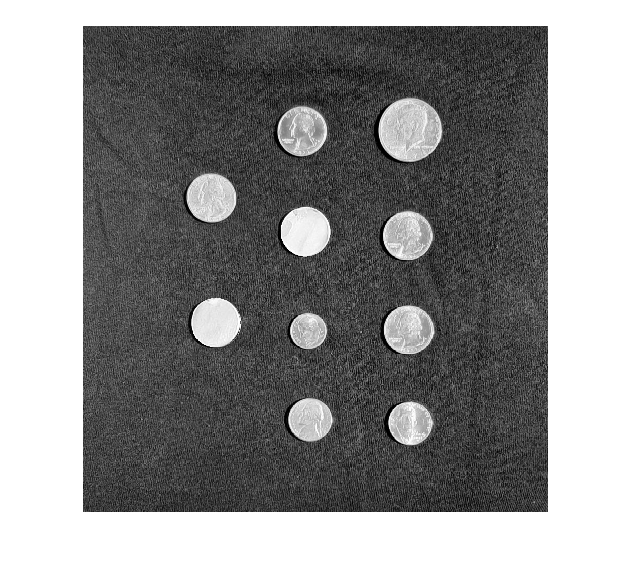

testImageIdx = randi([1,3]);
testCoinImage = imread("testCoinImage"+testImageIdx+".png");
figure,imshow(testCoinImage)

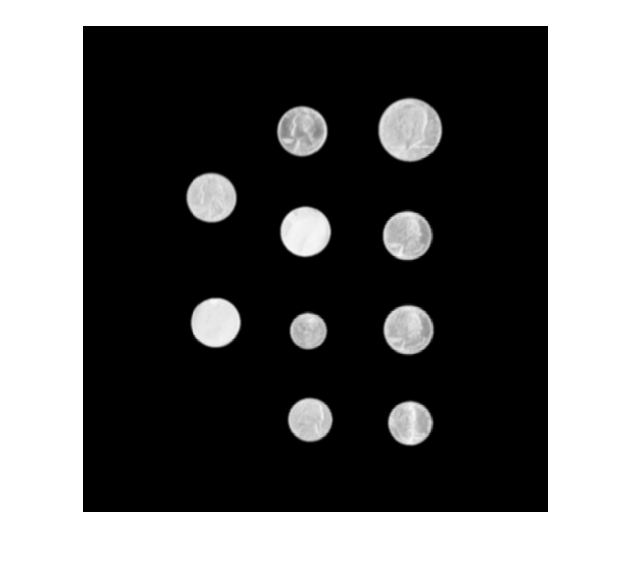


%call segmentation function
[testCoinMask,maskedTestCoinImage]= segmentImageCoinTest(testCoinImage);

testCoinImageFilt= imgaussfilt(maskedTestCoinImage,2);
imshow(testCoinImageFilt)

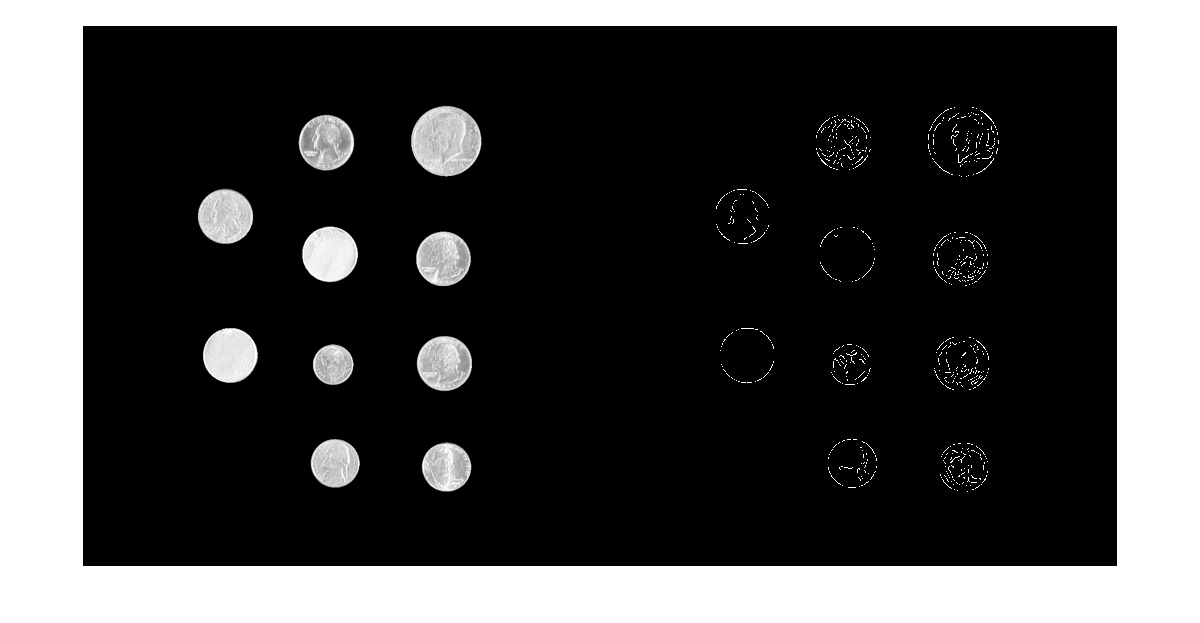

[faceEdgeMask, threshOut] = edge(testCoinImageFilt,"canny",0.1);
montage({maskedTestCoinImage,faceEdgeMask})